Семинар 5.

## **Тема:** "Спектральный портрет"

**Задание:** Изобразить спектральный портрет произвольной матрицы

clc;
clear;
N = 17

N = 17

A = randn(N)

A =     1.3451   -0.5802   -0.6042   -0.2035   -1.9528    1.1076    0.2195    0.1449    0.3899   -1.3391    0.3460    1.3065   -0.4344    0.4627   -0.0535    0.7337   -2.0221
   -0.1740   -0.1489   -1.6992   -1.4995   -0.4560    0.5468   -2.1185   -0.5194   -0.1266   -1.8435   -0.1325    0.6167    0.5658    0.8352   -0.1218   -0.5100   -1.4735
   -0.2613   -0.0563   -0.2474   -0.6210   -0.1585   -0.4866   -0.8525   -1.2605   -0.5272    1.3632   -1.3260   -0.3411    0.1920   -0.6809    0.7718   -0.5024    0.5292
    0.7917   -0.8610   -0.9487    1.8849   -0.8416    1.5772   -1.4361   -0.7348   -0.8238    0.2427    0.3214    0.7021   -0.0250   -0.0309    0.8430    0.1807   -0.8325
    1.1179   -0.3344    0.8307   -0.1799   -0.1013   -1.1577   -0.1783   -0.3610   -0.1184    0.1345   -0.7275   -1.3932    1.3523    1.4167   -0.3250    1.0452   -1.4758
   -0.2108   -1.7308   -0.3411   -0.6750    1.8826   -0.6078    0.9324   -0.2738   -0.3227    0.0255   -0.5389    0.2562    0.5966    0.2750 


% Вычисляем собственные значения
eigenvalues = eig(A);
step = 0.1

step = 0.1000

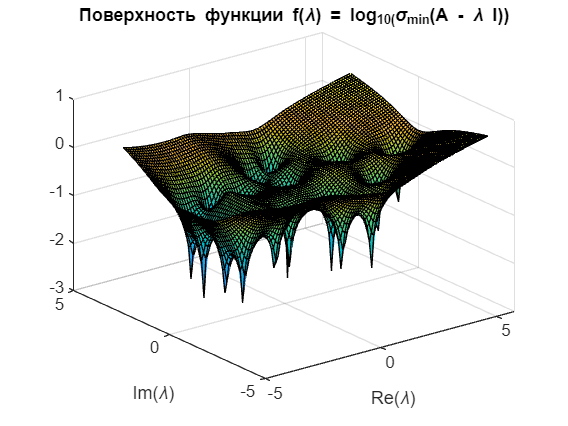

X = min(real(eigenvalues)) - 1:step:max(real(eigenvalues)) + 1;
Y = min(imag(eigenvalues)) - 1:step:max(imag(eigenvalues)) + 1;

% Инициализируем массив для хранения значений функции f(lambda)
f_values = zeros(length(X),length(Y));

% Вычисляем минимальное сингулярное число для каждого значения lambda
for i = 1:length(X)
    for j = 1:length(Y)
        f_values(i, j) = sigma_min(A - (complex(X(i), Y(j))) * eye(N));
    end;
end

% Построение поверхности
figure;
surf(X, Y, f_values');
title('Поверхность функции f(\lambda) = log_10(\sigma_{min}(A - \lambda I))');
xlabel('Re(\lambda)');
ylabel('Im(\lambda)');
grid on;

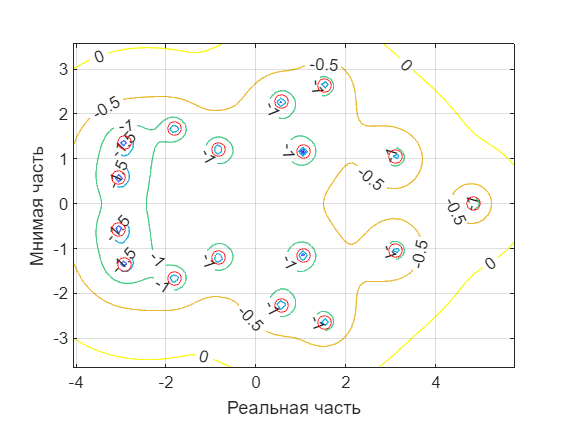


% Строим спектральный портрет
contour(X, Y, f_values', 'ShowText', 'on');
hold on; % Удерживаем текущий график для добавления собственных значений
plot(real(eigenvalues), imag(eigenvalues), 'ro', 'MarkerSize', 8, 'DisplayName', 'Собственные значения');
hold off; % Освобождаем график
xlabel('Реальная часть');
ylabel('Мнимая часть');
axis equal; % Устанавливаем равные масштабы по осям
grid on; % Включаем сетку

function min_singular_value = sigma_min(X)
    min_singular_value = log10(min(svd(X))); % Используем SVD для нахождения сингулярных чисел
end